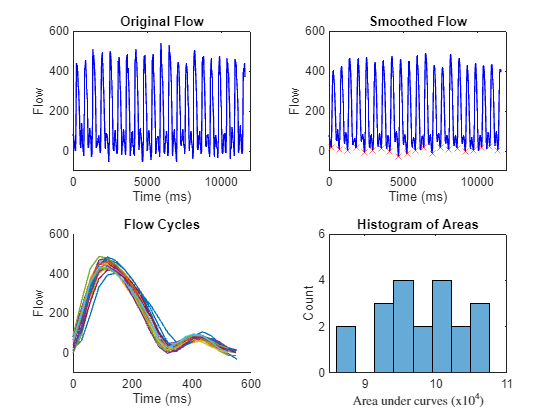

clear;clf;clc;
flowData = load("flow.csv"); % Loads Data into a variable flowData
smoothedFlowData = flowData; % Copys flow data to a smooth data so original can be saved
smoothedFlowData(:,2) = smoothdata(flowData(:,2),"gaussian","SamplePoints",flowData(:,1),"SmoothingFactor",0.25);
[troughs, cycle_times, cycle_flows, areas] = processFlow(smoothedFlowData); % Process flow
displayResults(flowData, smoothedFlowData, troughs, cycle_times, cycle_flows, areas); % Displays results of smoothed data

fprintf("The Mean and Std Deviation of the areas under the curve = %f +/- %f",mean(areas),std(areas));

The Mean and Std Deviation of the areas under the curve = 97909.897924 +/- 5861.644121